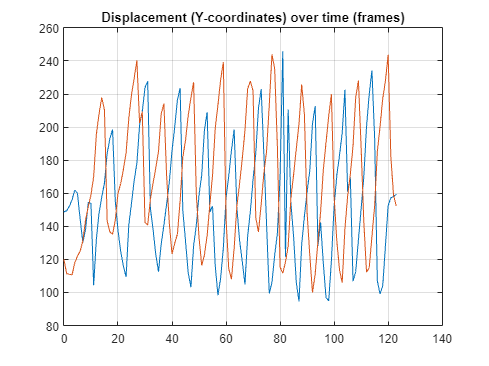


data = readmatrix('/Users/mikek/Desktop/Test_data/July10.23_1_HeidiOwen_Raw_2.MP4DLC_resnet50_String_model_2Jul3shuffle1_101500.csv');
% X/Y position values for data
Lx_pos = data(:,2);
Ly_pos = data(:,3);
Rx_pos = data(:,5);
Ry_pos = data(:,6);

% Frames, as a measure of time.
Frames = data (:,1);

% X/Y velocity values
Lx_vel = diff(Lx_pos) ./ diff(Frames);
Ly_vel = diff(Ly_pos) ./ diff(Frames);
Rx_vel = diff(Rx_pos) ./ diff(Frames);
Ry_vel = diff(Ry_pos) ./ diff(Frames);

% X/Y acceleration values
Lx_acc = diff(Lx_vel) ./ diff(Frames(1:end-1));
Ly_acc = diff(Ly_vel) ./ diff(Frames(1:end-1));
Rx_acc = diff(Rx_vel) ./ diff(Frames(1:end-1));
Ry_acc = diff(Ry_vel) ./ diff(Frames(1:end-1));

%figures
figure;
plot(Frames,Ly_pos,Frames,Ry_pos)
title ('Displacement (Y-coordinates) over time (frames)')
grid on;

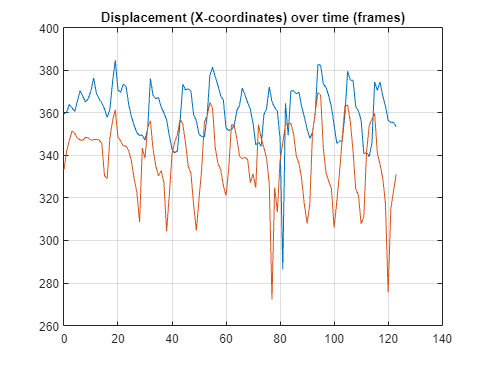


figure;
plot(Frames,Lx_pos,Frames,Rx_pos)
title ('Displacement (X-coordinates) over time (frames)')
grid on;

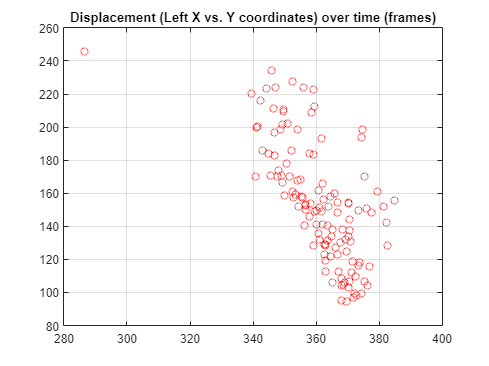


figure;
plot(Lx_pos,Ly_pos, 'ro')
title ('Displacement (Left X vs. Y coordinates) over time (frames)')
grid on;

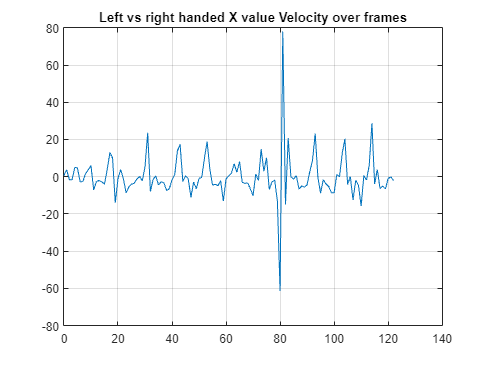


figure;
plot(Frames (1:end-1), Lx_vel);
title ('Left vs right handed X value Velocity over frames')
grid on;

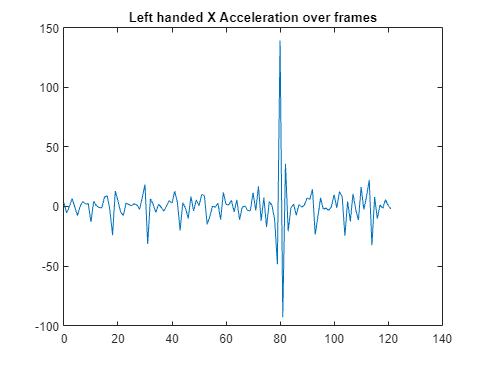


figure;
plot(Frames(1:end-2), Lx_acc);
title('Left handed X Acceleration over frames');


%correlation

ry= corrcoef(Ly_pos,Ry_pos);

disp(ry);

    1.0000   -0.5706
   -0.5706    1.0000




rx= corrcoef(Lx_pos,Rx_pos);

disp(rx)

    1.0000    0.2326
    0.2326    1.0000



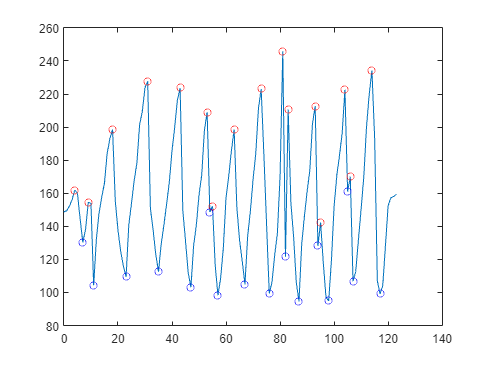


% Find peaks and their locations
[pos_peaks,pos_frame] = findpeaks(Ly_pos);
[neg_peaks,neg_frame] = findpeaks(-Ly_pos);
neg_peaks = -neg_peaks;

% Combine positive and negative peak locations, and sort them
total_peak_y= sort([pos_frame, neg_frame]);

%total_peak_y = Frames(frame);

%x-values corresponding to all peak locations
total_peak_x= Frames(total_peak_y);

% Calculate distances between all peaks in x
distances = diff(total_peak_x);

% Calculate the average distance
avg_distance = mean(distances);

% Plot the data and highlight the positive and negative peaks
figure;
plot(Frames, Ly_pos);
hold on;
plot(Frames(pos_frame), pos_peaks, 'ro');
plot(Frames(neg_frame), neg_peaks, 'bo');
hold off;


% Display the peak x-values, their distances, and average distance
disp('All peak X-values:');

All peak X-values:


disp(total_peak_x);

     4     7
     9    11
    18    23
    31    35
    43    47
    53    54
    55    57
    63    67
    73    76
    81    82
    83    87
    93    94
    95    98
   104   105
   106   107
   114   117



disp('Distances between all peaks:');

Distances between all peaks:


disp(distances);

     5     4
     9    12
    13    12
    12    12
    10     7
     2     3
     8    10
    10     9
     8     6
     2     5
    10     7
     2     4
     9     7
     2     2
     8    10



disp('Average distance between all peaks:');

Average distance between all peaks:


disp(avg_distance);

    7.3333    7.3333

